%problem 1
clear
clc
%setting up constants
x = 0 : 5 : 30

x =      0     5    10    15    20    25    30


f = [0, 9, 13, 14, 10.5, 12.0, 5]

f =          0    9.0000   13.0000   14.0000   10.5000   12.0000    5.0000


theta = [0.5, 1.4, 0.75, 0.90, 1.30, 1.48, 1.50]

theta =     0.5000    1.4000    0.7500    0.9000    1.3000    1.4800    1.5000


delta_x = 5

delta_x = 5

%producing work vector
work = zeros(1, length(x))

work =      0     0     0     0     0     0     0


for i = 1:length(x)
    work(i) = f(i) * cos(theta(i))
end

work =      0     0     0     0     0     0     0


work =          0    1.5297         0         0         0         0         0


work =          0    1.5297    9.5120         0         0         0         0


work =          0    1.5297    9.5120    8.7025         0         0         0


work =          0    1.5297    9.5120    8.7025    2.8087         0         0


work =          0    1.5297    9.5120    8.7025    2.8087    1.0881         0


work =          0    1.5297    9.5120    8.7025    2.8087    1.0881    0.3537



%trapezoidal approx
total = zeros(1, length(work))

total =      0     0     0     0     0     0     0


for i = 2:length(work)
    total(i) = total(i) + ((work(i - 1) + work(i))/2) * delta_x
end

total =          0    3.8243         0         0         0         0         0


total =          0    3.8243   27.6041         0         0         0         0


total =          0    3.8243   27.6041   45.5362         0         0         0


total =          0    3.8243   27.6041   45.5362   28.7782         0         0


total =          0    3.8243   27.6041   45.5362   28.7782    9.7420         0


total =          0    3.8243   27.6041   45.5362   28.7782    9.7420    3.6044



sum(total)

ans = 119.0892

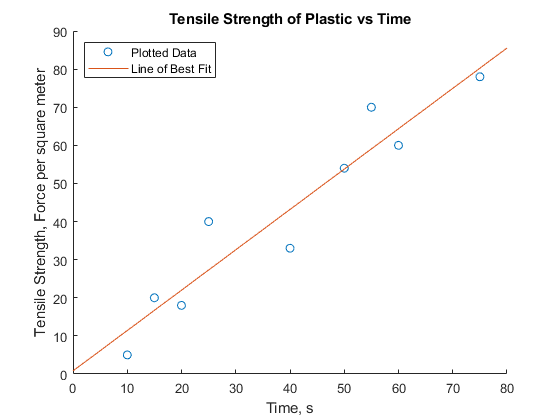



%setting up constants
clear
clc
t = [10, 15, 20, 25, 40, 50, 55, 60, 75];
ten_strength = [5, 20, 18, 40, 33, 54, 70, 60, 78];
x = t;
y = ten_strength;
%building the matrix and vectors
A = [ones(length(x), 1), x'];
b = y';

%solving for x_ls
x_ls = (A' * A) \ (A' * b);

%generating plotting vectors and plotting
x_vec = linspace(0, 80);

lin_fit = (x_ls(2) * x_vec) + x_ls(1);
scatter(x, y, "o");
hold on;
plot(x_vec, lin_fit);
title("Tensile Strength of Plastic vs Time")
xlabel("Time, s")
ylabel("Tensile Strength, Force per square meter")
legend("Plotted Data", "Line of Best Fit", "Location", "northwest")